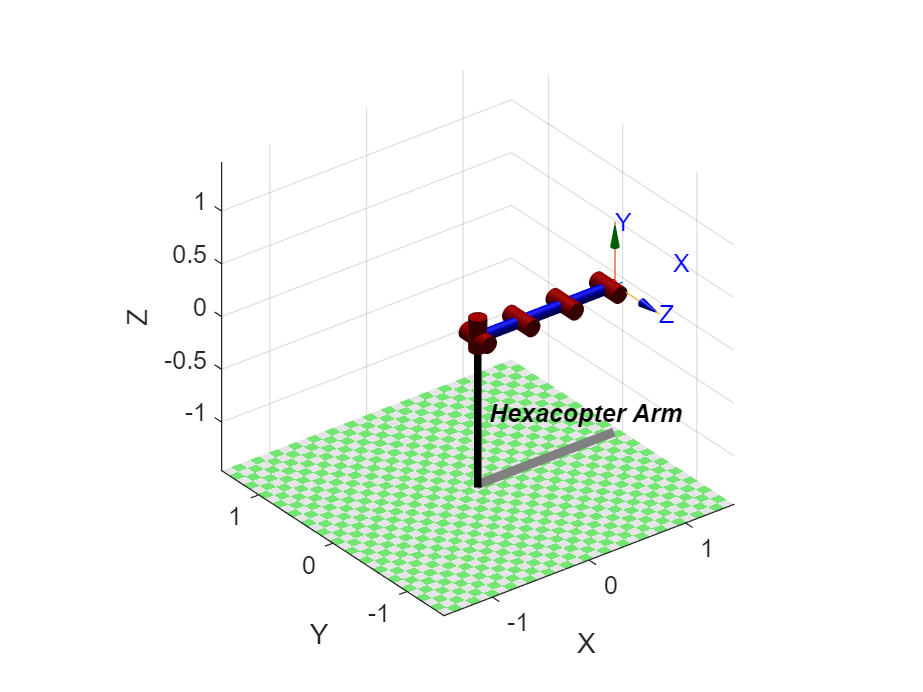

%1a--------DH--------%
clear
syms q1 q2 q3 q4 q5 

%Defining link-lengths. All values [m]
L1 = .04; L2 = .45; L3 = .45; L4 = .45; L5 = .07;

%Creating zero angle variable
qz = ([0 0 0 0 0 ]);

%% 1a
%Connecting the links with the DH-parameters: 
%| theta | d | a | alfa |  
L(1) = Link ( [0 -L1 0 pi/2]);
L(2) = Link ( [0 0 L2 0] );
L(3) = Link ( [0 0 L3 0] );
L(4) = Link ( [0 0 L4 0] );
L(5) = Link ( [0 0 L5 0] );

%Creating an object of the DH-parameters 
RobotArm = SerialLink(L);
RobotArm.name = 'Hexacopter Arm';

%plotting our arm with all angles set to zero
RobotArm.plot(qz)

%------------Show equivalence------------%
Q1 = 0; Q2 = 0; Q3 = 0; Q4 = 0; Q5 = 0; 
Qz = [Q1 Q2 Q3 Q4 Q5];

T01 = [cos(Q1), -sin(Q1), 0, 0; 
    sin(Q1), cos(Q1), 0, 0; 
    0, 0, 1, -1/25; 
    0, 0, 0, 1];
T12 = [cos(Q2), -sin(Q2), 0, 9/20; 
    0, 0, -1, 0; 
    sin(Q2), cos(Q2), 0, 0; 
    0, 0, 0, 1];
T23 = [cos(Q3), -sin(Q3), 0, 9/20; 
    sin(Q3), cos(Q3), 0, 0; 
    0, 0, 1, 0; 
    0, 0, 0, 1];
T34 = [cos(Q4), -sin(Q4), 0, 9/20; 
    sin(Q4), cos(Q4), 0, 0; 
    0, 0, 1, 0; 
    0, 0, 0, 1];
T45 = [cos(Q5), -sin(Q5), 0, 7/100;
    sin(Q5), cos(Q5), 0, 0;
    0, 0, 1, 0; 
    0, 0, 0, 1];

T05Manually = T01*T12*T23*T34*T45

T05Manually =     1.0000         0         0    1.4200
         0         0   -1.0000         0
         0    1.0000         0   -0.0400
         0         0         0    1.0000


T05dh = RobotArm.fkine(qz)

 

T05dh = 
         1         0         0      1.42
         0         0        -1         0
         0         1         0     -0.04
         0         0         0         1


qFromInverseKinematics = RobotArm.ikine(T05dh, 'mask', [1 1 1 0 0 0])

qFromInverseKinematics =      0     0     0     0     0


%  {B} => Base;   {C} => Camera;  {F} => Fruit;
R = eye(3);

% from {B} to {E}
bPe = [0.24 0 0.7];
bTe = rt2tr(R, bPe)

bTe =     1.0000         0         0    0.2400
         0    1.0000         0         0
         0         0    1.0000    0.7000
         0         0         0    1.0000



% from {B} to {C}
bPc = [0.24 0 0.7];
bTc = rt2tr(R, bPc)

bTc =     1.0000         0         0    0.2400
         0    1.0000         0         0
         0         0    1.0000    0.7000
         0         0         0    1.0000


% from {C} to {F}
cPf = [1.16 0 -.7];
cTf = rt2tr(R, cPf)

cTf =     1.0000         0         0    1.1600
         0    1.0000         0         0
         0         0    1.0000   -0.7000
         0         0         0    1.0000


bTf = bTc*cTf

bTf =     1.0000         0         0    1.4000
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


% finding angles
qFruit = RobotArm.ikine(bTf,'mask',[1 1 1 0 0 0])

qFruit =    -0.0000   -0.1663    0.1570    0.2346    0.0373


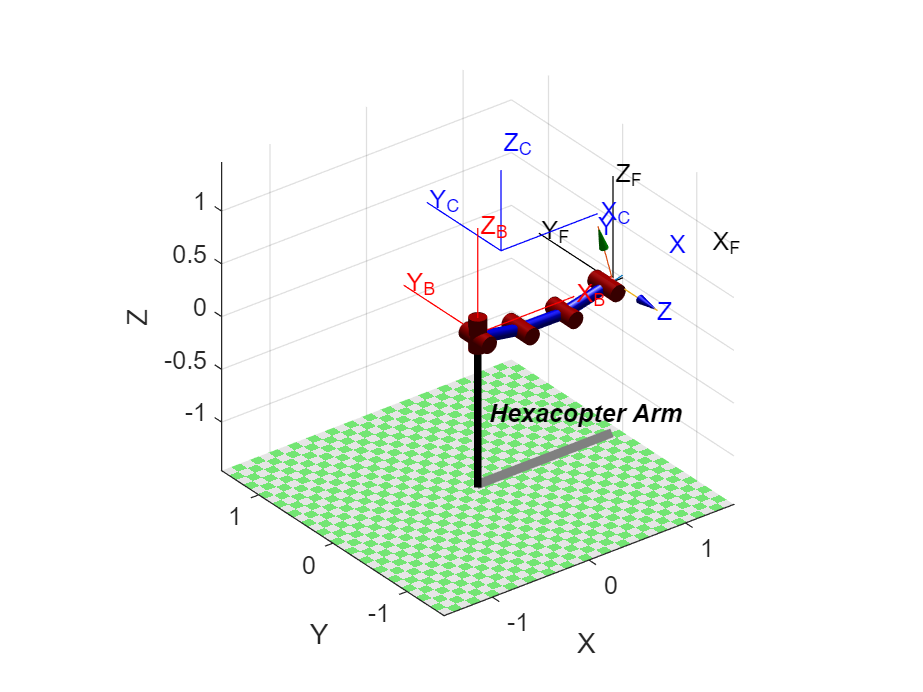

%base frame 
hold on
trplot(eye(3),'color','r','frame','B')

%camera frame
trplot(bTc,'color','b','frame','C')

%fruit frame
trplot(bTf,'color','k','frame','F')
RobotArm.plot(qFruit)

grid on

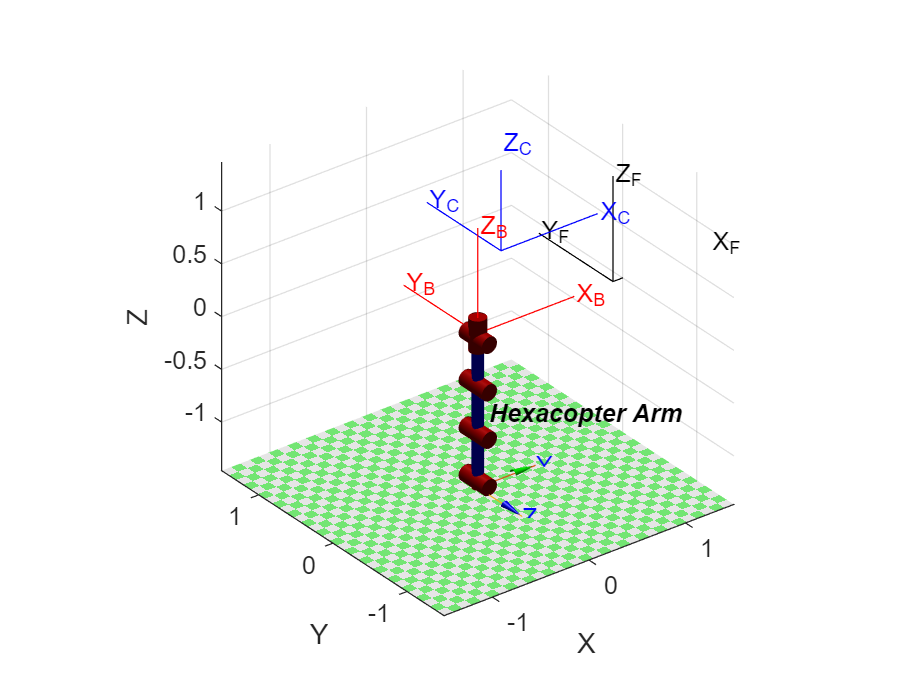

%------------Trajectory planning------------% 
%RobotArm.teach
t = [0:0.05:2];

qStep1 = [0 -pi/2 0 0 0];                                            % flying position without fruit     
qStep2 = [0 -pi/2 deg2rad(60) deg2rad(60)  deg2rad(30)];             % fruit detected
qStep3 = qFruit;                                                     % reaching fruit
qStep4 = [0 -pi/2 deg2rad(60) deg2rad(60)  deg2rad(30)];             % picking fruit                                       % picking the fruit
qStep5 = [0 -pi/2 0 0  0];                                           % flying position with fruit
                                

%Trajectory planing joint space
qi1 = mtraj(@lspb, qStep1, qStep2(1,:), t);
qi2 = mtraj(@lspb, qStep2(end,:), qStep3(1,:), t);
qi3 = mtraj(@lspb, qStep3(end,:), qStep4(1,:), t);
qi4 = mtraj(@lspb, qStep4(end,:), qStep5(1,:), t);

Q = [qi1; qi2; qi3; qi4;];

RobotArm.plot(Q)

%---------Differential Kinematics------------%

%Defining 200g on end-effector
wFruit = [0 0 .2 0 0 0]';

%Defining jacob0 matrix
qJacbi = RobotArm.jacob0(qFruit)'*wFruit;
forceN = abs(qJacbi')

forceN =          0    0.2800    0.1912    0.1012    0.0135
